% Define the data for lower limit, upper limit, and frequency
lowerLimits = [10,20,30,40,50,60,70]; 
upperLimits = [20,30,40,50,60,70,80]; 
frequencies = [1,3,11,21,43,32,9];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

        10            20            1    
        20            30            3    
        30            40           11    
        40            50           21    
        50            60           43    
        60            70           32    
        70            80            9    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 54.50


fprintf('Median: %.2f\n', medianValue);

Median: 55.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 55.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 12.15


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 56.00


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: -1.00


fprintf('Karl: %.2f\n', Karl);

Karl: -0.04


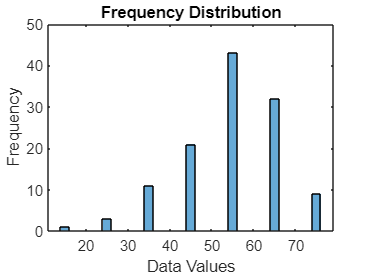


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');